Aplicamos PCA Y NMF a parches ABF que únicamente contienen información sobre la celta unidad STO.

clc, clear, close all

% Cargamos los datos
X_train = readmatrix('clean_patches/clean_stack.csv');

% Indicamos tamaño de los parches
m = 40;

% Escogemos un caso para visualizar
c = 1;

## Descomposición PCA $(X = UV')$

% Hacemos uso del algoritmo implementado en MATLAB
% (requiere "Statistics and Machine Learning Toolbox")
[V,U,s2] = pca(X_train);

% Nos quedamos con los dos primeros coeficientes porque son los que tienen
% una mayor varianza (s2)
disp("Varianza de 4 primeras PC")

Varianza de 4 primeras PC


disp(s2(1:4))

   13.2174
    8.9300
    7.7467
    7.1205



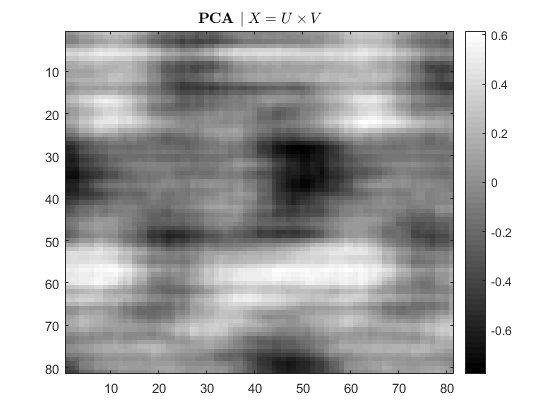


% Visualizamos las dos componentes principales escogidas
N = 4;
U = U/max(max(abs(U)));

figure(), clf
colormap gray; colorbar
X_ = U(:,1:N)*V(:,1:N)';
X_ = X_/max(max(abs(X_)));
I_ = reshape(X_(3,:),2*m+1,2*m+1);
imagesc(I_), colorbar
title("\textbf{PCA }$| \; X = U \times V$","Interpreter","latex")

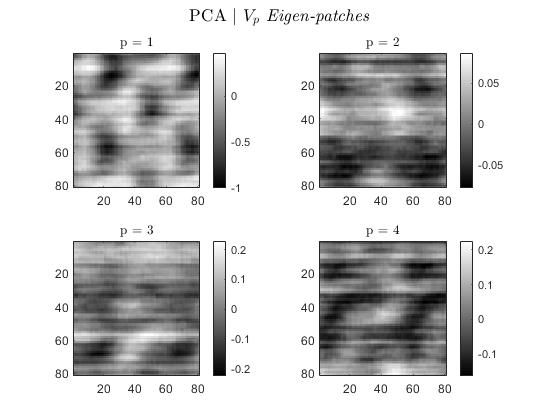


figure(), clf
colormap gray; colorbar
sgtitle("PCA $|$ $V_p$ \textit{Eigen-patches}","Interpreter","latex")

for i = 1:N
    X_ = U(:,i)*V(:,i)';
    X_ = X_/max(max(abs(X_)));
    I_ = reshape(X_(c,:),2*m+1,2*m+1);
    subplot(2,2,i)
    imagesc(I_), colorbar
    title("p = " + num2str(i),"Interpreter","latex")
end

## Descomposición NMF

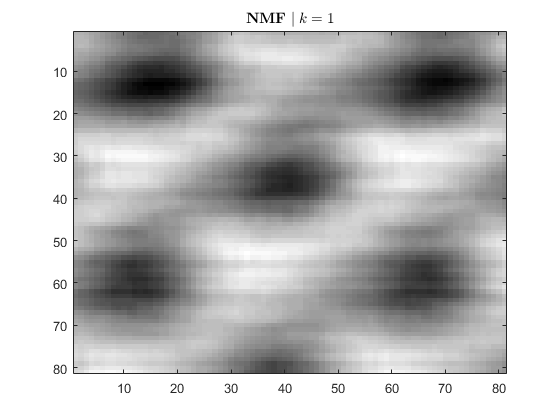

% Realizamos la factorización NMF
[Un,Vn] = nnmf(X_train,1);

% Mostramos el resultado
X_ = Un(:,1)*Vn(1,:);
X_ = X_/max(max(abs(X_)));
I_ = reshape(X_(c,:),2*m+1,2*m+1);

figure(), clf
colormap gray; colorbar
imagesc(I_)
title("\textbf{NMF }$| \; k = 1$","Interpreter","latex")